% EDP tutorial with a 2d example
clear all
close all
rng('default');
rng(1);

% time-series generation
T = 100;

% default EDM structure
[mdlstruct] = init_mdl_struct(2); % the input is the number of species

% data generation using a ricker model
param={[0.1 0.1],[3 0.5; 0.4 3],[3 3]}; % ricker model parameters
mdlstruct.model = @(x,u,is_det) dyn_ricker(x,u,is_det,param);


% random control
u = rand(T,2)/2;

% data generation
[mdlstruct.data,mdlstruct.control_data] =  data_generation(mdlstruct.model,[0.5 0.5],u,T)

mdlstruct = struct with fields:
           n_dim: 2
             tau: 1
      n_lags_max: 1
            name: {'x_1'  'x_2'}
           model: @(x,u,is_det)dyn_ricker(x,u,is_det,param)
            data: [100×2 double]
    control_data: [100×2 double]


mdlstruct = struct with fields:
           n_dim: 2
             tau: 1
      n_lags_max: 1
            name: {'x_1'  'x_2'}
           model: @(x,u,is_det)dyn_ricker(x,u,is_det,param)
            data: [100×2 double]
    control_data: [100×2 double]


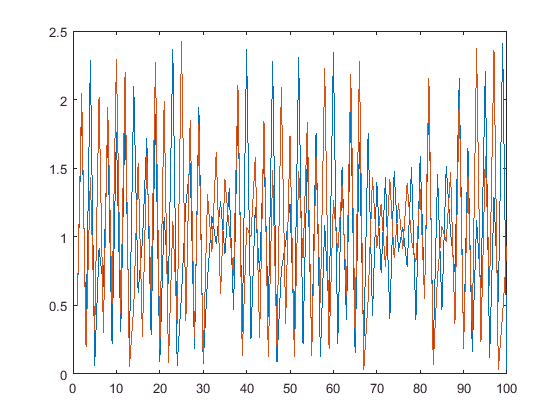


%different kinds of control exist, we need to specify which one we use here
mdlstruct.control_type =  'rate';
mdlstruct.control_param =  [1 1]; % both  dimensions are controlled



% data display
figure;plot(mdlstruct.data)


% built-in data display
data_show(mdlstruct)


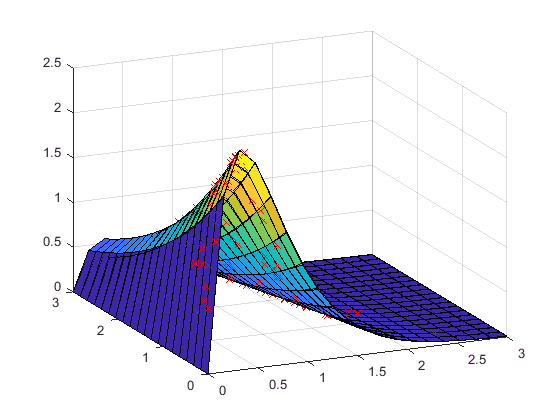

% gp regression
% this step can be skipped if a model already exists, otherwise a GP is
% fitted to the data
% fills the field mdlstruct.model with the fitted gp
% fills the field mdlstruct.model_stats with statistics computed during the
% GP regression

% default gp structure
mdlstruct.gp = init_gp();

% we now fit the gp with the data in mdlstruct
mdlstruct = fit_gp(mdlstruct);


gp_show(mdlstruct)